# Seminar 8 - Extended Kalman filter (EKF) and iterated EKF (IEKF)

**Authors: **Ing. David Vošahlík, prof. Ing. Vladimír Havlena, CSc.

## Introduction

Classical Kalman filter is limited onto a linear system that is rarely to see in real life. Linearization in some operating point could solve the problem for some cases. Fortunately for the rest there are extensions to the kalman filter for nonlinear systems that work better especially when the linearization in neighborhood of the operating point is not sufficient. On the other hand these are more computationaly extensive, harder to implement and consume more resources. Inbetween such methods are e.g. extenended kalman filter EKF and it's iterated version IEKF. These will be studied in this seminar. 

Main idea of EKF is to linearize the system in the current state and input. Iterated EKF just adds more iterations of EKF data steps until the difference of the state estimate in one data step is negligible.  

## Battery state of charge estimation - EKF, IEKF and KF

Let's consider a Li-ion battery that is described by the following equations


$$\begin{array}{l}
\frac{\mathrm{d}\;i}{\mathrm{d}\;t}=10\left(u-i\right)\;+\frac{{\textrm{dw}}_1 }{\textrm{dt}}\;,\\
\dot{\textrm{SOC}} =\frac{1}{Q_r }i+\frac{{\textrm{dw}}_2 }{\textrm{dt}}
\end{array}$$


where $i$ is current of the battery, $Q_r$ is capacity of the battery, SOC is state of charge, $\textrm{dw}~N\left(0,Q_c \right)$ is process noise and $u$ is commanded current. Parameters of the system will be stated directly in the pre-prepared script. Input to the system is also prepared for you.  Let's define the state of the battery as $x=\left\lbrack \begin{array}{c}
i\\
\textrm{SOC}
\end{array}\right\rbrack$. Assume that we are able to measure open circuit voltage of the battery. So the measurement eaution is:

$y=\textrm{OCV}\left(\textrm{SOC}\right)+e$,

where $\textrm{OCV}\left(\textrm{SOC}\right)$ is function fitted on the data provided by the battery manufacturer (or measured in test cell)  and $e$ is measurement noise. Both the measurement and process noise covariances (Q and R) are valued in the pre-prepared script.

Your task will be:

- Discretize the system (e.g. using euler method)

- Simulate the system

- Implement the extended kalman filter EKF

- Implement the iterated extended kalman filter IEKF

- Implement the clasical kalman filter KF

- Compare the estimates (plot the estimates and print the resulting RMSE) for KF, EKF and IEKF

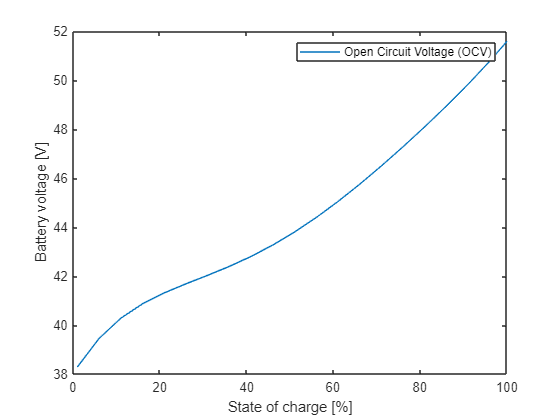

N =1000;                                                 % num of steps
Ts = 0.01;                                              % time step
C_AH = 2;                                               % Ah
Qr = C_AH*36;                                           % Convert to charging constant
taui = 10;                                              % time constant for current tracking

Qd  = 0.1*[Ts^3/3 Ts^2/2; Ts^2/2 Ts];                   % process noise covariance (in discrete time already)
R  = 0.1;                                               % measurement noise covariance
QL = chol(Qd,'lower');

% Nonlinear system functions
f = @(x, u, v)([(taui*(u - x(1))*Ts + x(1)); ...
    (1/Qr*x(1))*Ts + x(2)]+ QL*v);
h = @(x,e)(38 + 0.295*x(2) - 0.01*x(2)^2 + 1.9694e-04*x(2)^3 - 1.652e-06*x(2)^4 + 5.234e-09*x(2)^5 + sqrt(R)*e);

SOC = [1:5:100 100];
OCV = zeros(numel(SOC), 1);
for i = 1:numel(SOC)
    OCV(i) = h([0 SOC(i)], 0);
end
figure;
plot(SOC, OCV);
legend('Open Circuit Voltage (OCV)');
ylabel('Battery voltage [V]');
xlabel('State of charge [%]');

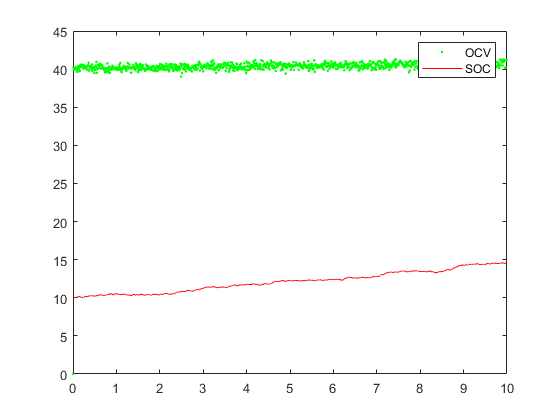

% Jacobians
fd = @(x)([(1 - Ts*taui) 0;Ts/Qr 1]);
hd = @(x)([0 (0.2945 - 2*0.0102*x(2) + 3*1.9694e-04*x(2)^2 - 4*1.6518e-06*x(2)^3 + 5*5.2344e-09*x(2)^4)]);

% Init
T = (0:N-1)*Ts;
X = zeros(2,N);
Y = zeros(1,N);
U = 40*abs(randn(1,N));

% Simulate
x0 = [1;10];
X(:,1) = x0;
for k= 2:N
    x = f(X(:,k-1), U(:,k-1),randn(2,1));   % state measurements with gwn
    y = h(x,randn);                         % output measurements with gwn
    X(:,k) = x;
    Y(:,k) = y;
end

% Plot simulation
figure;
plot(T,Y,'g.',T,X(2,:),'r-');
legend('OCV', 'SOC');



%% EKF

x0 = [4;30];       % Slightly off
P0 = 300*eye(2);

% IEKF
eps = .01;

% KF
xp = [40; 30];
A_KF = fd(xp);
B_KF = [taui*Ts;0];
C_KF = hd(xp);

% initialize
xhat_EKF = x0;
xhat_KF = x0;
P_EKF = P0;
P_IEKF = P0;
P_KF = P0;
XXhat_EKF = zeros(size(xhat_EKF,1),length(Y));
XXhat_EKF(:,1) = xhat_EKF;
XXhat_IEKF = zeros(size(xhat_EKF,1),length(Y));
XXhat_IEKF(:,1) = xhat_EKF;
XXhat_KF = zeros(size(xhat_EKF,1),length(Y));
XXhat_KF(:,1) = xhat_KF;
PP = zeros(size(P_EKF,1),size(P_EKF,2),length(Y));


for k=2:length(Y)
    
    % Data step EKF
    x0_IEKF = xhat_EKF;
    C = hd(xhat_EKF);                                           % matrix C(t) approx
    L = P_EKF*C'/(C*P_EKF*C' + R);                              % kalman gain for data step
    P_EKF = P_EKF - L*(C*P_EKF*C' + R)*L';                      % P(t|t) estimate
    xhat_EKF = xhat_EKF + L*(Y(k) - h(xhat_EKF,0));             % xhat(t|t) estimate
    
    % Data step IEKF
    xhat_IEKF = xhat_EKF;
    i = 1;
    while true
        C = hd(xhat_IEKF);                                      % matrix C(t) approx
        L = P_IEKF*C'/(C*P_IEKF*C' + R);                        % kalman gain for data step
        xhat_iekf_new = x0_IEKF + L*(Y(k) - h(xhat_IEKF,0) - C*(x0_IEKF - xhat_IEKF));  % xhat(t|t) estimate
        if i > 30
            P_IEKF =  P_IEKF - L*(C*P_IEKF*C' + R)*L';          % P(t|t) estimate
            xhat_IEKF = xhat_iekf_new;
            break;
        end
        if norm(xhat_iekf_new - xhat_IEKF) < eps
            P_IEKF =  P_IEKF - L*(C*P_IEKF*C' + R)*L';          % P(t|t) estimate
            xhat_IEKF = xhat_iekf_new;
            break;
        end
        xhat_IEKF = xhat_iekf_new;
        i = i +1;
    end
    
    % Data step KF
    L = P_KF*C_KF'/(C_KF*P_KF*C_KF' + R);                   % kalman gain for data step
    P_KF = P_KF - L*C_KF*P_KF;                              % P(t|t) estimate
    xhat_KF = xhat_KF + L*(Y(k) - h(xp,0) - C_KF*xhat_KF);  % xhat(t|t) estimate
    
    
    % Time step EKF
    A = fd(xhat_EKF);                                       % matrix A(t) approx
    xhat_EKF = f(xhat_EKF, U(:,k), zeros(2,1));             % xhat(t+1|t) estimate
    P_EKF = A*P_EKF*A' + Qd;                                 % P(t+1|t) estimate
    
    % Time step IEKF
    A = fd(xhat_IEKF);                                      % matrix A(t) approx
    xhat_IEKF = f(xhat_IEKF, U(:,k), zeros(2,1));           % xhat(t+1|t) estimate
    P_IEKF = A*P_IEKF*A' + Qd;                               % P(t+1|t) estimate
    
    % Time step KF
    xhat_KF = A_KF*xhat_KF + B_KF*U(:,k);                   % xhat(t+1|t) estimate
    P_KF = A_KF*P_KF*A_KF' + Qd;                             % P(t+1|t) estimate
    
    XXhat_EKF(:,k) = xhat_EKF;
    XXhat_IEKF(:,k) = xhat_IEKF;
    XXhat_KF(:,k) = xhat_KF + xp;
    PP(:,:,k) = P_EKF;
end

rmse_ekf = sqrt(mean((X(2,10:end)-XXhat_EKF(2,10:end)).^2))

rmse_ekf = 0.2671

rmse_iekf = sqrt(mean((X(2,10:end)-XXhat_IEKF(2,10:end)).^2))

rmse_iekf = 0.2672

rmse_kf = sqrt(mean((X(2,10:end)-(XXhat_KF(2,10:end))).^2))

rmse_kf = 10.2493

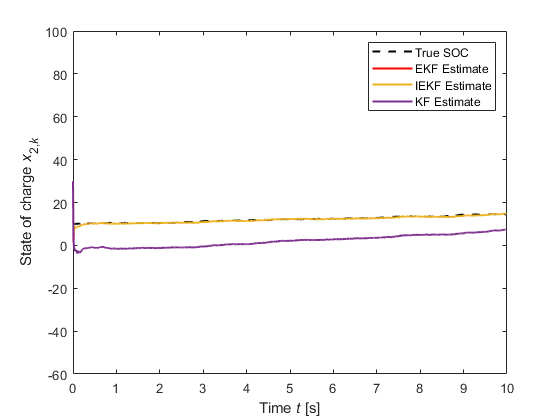


figure;
p=plot(T,X(2,:),'--k',T,XXhat_EKF(2,:),'r', T,XXhat_IEKF(2,:), T,XXhat_KF(2,:), 'Linewidth',1.5);
legend('True SOC','EKF Estimate', 'IEKF Estimate', 'KF Estimate');
xlabel('Time{\it t} [s]');
 ylabel('State of charge {\it{x}}_{2,{\it{k}}}')
 ylim([-60 100]);

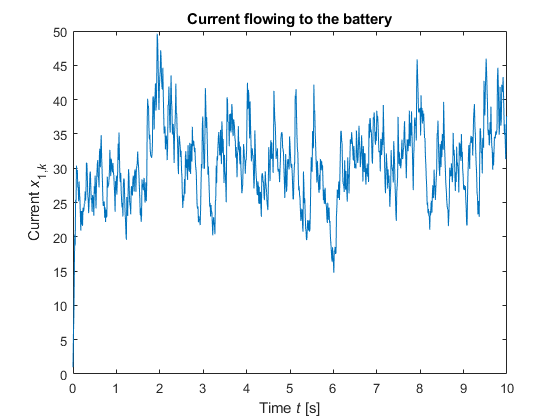


figure;
plot(T, X(1,:));
title('Current flowing to the battery')
xlabel('Time{\it t} [s]');
 ylabel('Current {\it{x}}_{1,{\it{k}}}')